# Van der Pol Oscillator

Let's learn and define limits of the Van der Pol oscillator (or attractor)

## 1. Initialization

clear variables
close all
clc

## Add path

functions_path = 'functions';
addpath(functions_path)

## Inputs

Constants

% Constants
g = 9.81; % m/s
b = 2*pi;

% Number of samples
N_p = 1; % Used for VdP

% Scalling factors
k1 = 1.5; % lambda_1 = k1*lambda_p./(b*A^2)
k2 = 3.5; % lambda_2 = k2*lambda_p*b/A^2
k3 = 0.8; %lambda_3 = k3*lambda_p*b
alpha_s = 1/2;

% Ranges for Initial Conditions (ICs) ---
x0_range = [-0.03; 0.03];
x0p_range = [-0.3; 0.3];

% Time to simulate
t_end = 15; % second

% % These are for the commented-out sinusoidal example
A_y = 0;          % Amplitude of bridge acceleration [m/s^2]
f_bridge = 0.9;     % Frequency of bridge acceleration [hz = 1/s]
omega_y = 2*pi*f_bridge;    % Frequency of bridge acceleration [rad/s]
% T_y = 2 * pi / omega_y; % Period of the bridge

Distribution parameters

% Mass
mu_m = 71.91;  % kg mean
sigma_m = 14.89; % kg standard deviation
m_min = 40; % kg minimum value
m_max = 120; % kg maximum value

% Frequency and walking velocity
mu_v = 1.3; % m/s
sigma_v = 0.13; % m/s
v_min = 0.8; % m/s
v_max = 2; % m/s 
rhofv = 0.51; 
mu_freq = 1.8; % hz                                                     
sigma_freq = 0.11;  % hz
freq_min = 1.2; % hz
freq_max = 2.4; % hz                                                      
mu_fv = [mu_freq; mu_v];
sigmas = [sigma_freq; sigma_v];
rhos = [1 rhofv; rhofv 1];
min_fv = [freq_min, v_min];
max_fv = [freq_max, v_max];
covariance_fv = diag(sigmas)*rhos*diag(sigmas);

% Van der Pol oscillator parameters
mu_ai = 1.0;
ai_min = 0.8;
ai_max = 2*mu_ai - ai_min; % ai_max = mu_ai + (mu_ai - ai_min)
sigma_ai = (ai_max - mu_ai)/3;
mu_lambdai = 10;
lambdai_min = 8;
lambdai_max = 2*mu_lambdai - lambdai_min;
sigma_lambdai = (lambdai_max - mu_lambdai)/3;


## Sampling

sample_m = sampling_distributions('normal', N_p, 'mu_normal', mu_m, 'sigma_normal', sigma_m, 'min_value', m_min, 'max_value', m_max);
samples = sampling_distributions('multivariatenormal', N_p, 'mu_multi', mu_fv, 'covariance_multi', covariance_fv, 'min_value', min_fv, 'max_value', max_fv);
samples_freq = samples(:,1);
samples_v = samples(:,2);
samples_ai = sampling_distributions('normal', N_p, 'mu_normal', mu_ai, 'sigma_normal', sigma_ai, 'min_value', ai_min, 'max_value', ai_max);
samples_lambdai = sampling_distributions('normal', N_p, 'mu_normal', mu_lambdai, 'sigma_normal', sigma_lambdai, 'min_value', lambdai_min, 'max_value', lambdai_max);
v_p_0_samples = x0_range(1) + (x0_range(2) - x0_range(1)) * rand(N_p, 1);
v_p_dot_0_samples = x0p_range(1) + (x0p_range(2) - x0p_range(1)) * rand(N_p, 1);

Transform sampling to be readable by the VdP oscillator

% Define equation parameters as vectors (1 x N_p)
% We assume identical parameters for all pedestrians for simplicity,
% but they could be different (e.g., mass = 60 + 20*rand(1, N_p))
A = 2*1/b^2;
mass = sample_m.';             % Mass [kg]
W = mass*g; % weight [kg * m/s]
f_vertical = samples_freq.';
f_lateral_p = f_vertical/2;   % f_vertical = 1.8
omega_p = b.*f_lateral_p;   % Natural frequency [rad/s]

% Coefficients are now (1 x N_p) vectors, calculated element-wise
lambda_p = samples_lambdai.';
a_p = samples_ai.';             % Constant parameter
lambda_1 = k1*lambda_p./(b*A^2);   % Coefficient for v_dot^2
lambda_2 = k2*lambda_p*b/A^2;   % Coefficient for v^2
lambda_3 = k3*lambda_p*b;   % Coefficient for a_p

% Initial conditions of the pedestrian oscillator
x0_matrix = [v_p_0_samples, v_p_dot_0_samples];
x0 = reshape(x0_matrix.', [], 1);

## Models

%% Bridge lateral acceleration (test)
ypp_t = @(t) A_y*sin(omega_y*t) + A_y*0.7*sin(2*pi*0.5*t);

%% Create equation of motion of the pedestrian
f = @(t, x) eom_multi_pedestrian(t, x, N_p, lambda_1, lambda_2, lambda_3, a_p, omega_p, ypp_t);

## Solve with ODE45

% Solve
tspan = [0 t_end];
[t, x] = ode45(f, tspan, x0); % x are the states (v_p and v_p_dot)
ypp_values = arrayfun(ypp_t, t); % (T x 1) vector
v_p = x(:, 1:2:end);
v_p_dot = x(:, 2:2:end);

% With v_p and v_p_dot we can compute the lateral acceleration of the
% oscillator (pedestrian), with this we can calculate lateral force.
v_p_ddot = -(lambda_1.*v_p_dot.^2 + lambda_2.*v_p.^2 - lambda_3.*a_p).*v_p_dot - omega_p.^2.*v_p - ypp_values;

% Compute lateral force
F_lateral = alpha_s.*mass.*v_p_ddot; % The "/2" is given that the amplitude is twice the required

% Calculate the TOTAL lateral force by summing all pedestrians
F_total = sum(F_lateral,2); % each row is time, each column is pedestrian

## Figures

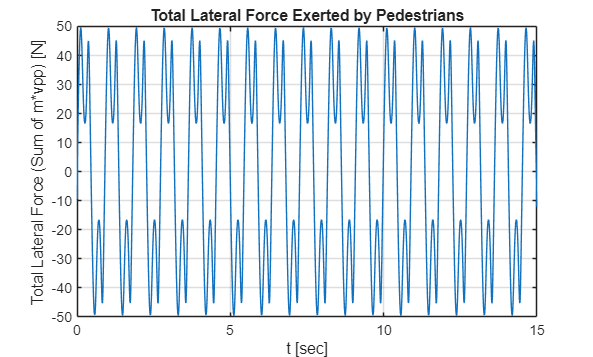

% Total Lateral Force
figure
plot(t, F_total)
title('Total Lateral Force Exerted by Pedestrians')
xlabel('t [sec]')
ylabel('Total Lateral Force (Sum of m*vpp) [N]')
grid on

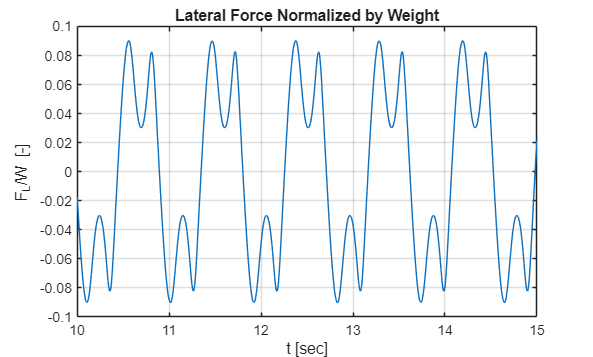

% Individual Pedestrian Forces
figure
plot(t, -F_lateral./W) % MATLAB plots each column as a separate line
title('Lateral Force Normalized by Weight')
xlim([10, t_end])
xlabel('t [sec]')
ylabel('F_L/W [-]')
grid on

This plot should look like this:

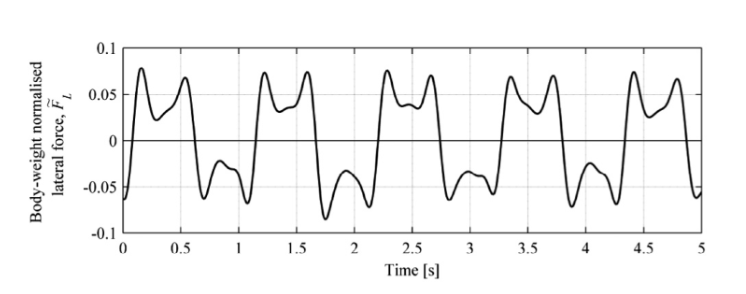

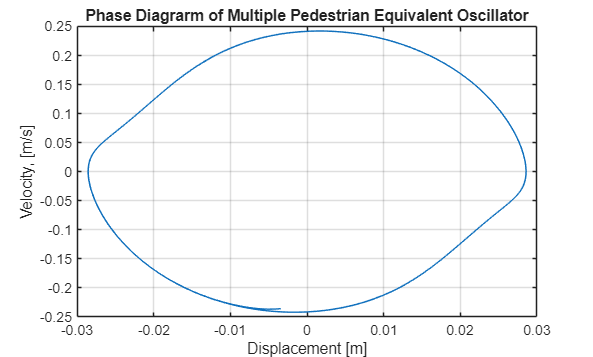

% Phase Plot 
figure;
plot(v_p, v_p_dot);
title('Phase Diagrarm of Multiple Pedestrian Equivalent Oscillator');
xlabel('Displacement [m]');
ylabel('Velocity, [m/s]');
grid on;

## Functions: 

Equation of Motion for Multiple Pedestrians

% This function must be at the end of the script or in its own .m file
function dxdt = eom_multi_pedestrian(t, x, N_p, lambda_1, lambda_2, lambda_3, a_p, omega_p, ypp_t)
    % 1. Initialize the output vector
    dxdt = zeros(2 * N_p, 1);

    % 2. Extract current states in a vectorized way
    % x is (2*N_p x 1)
    v_p     = x(1:2:end); % (N_p x 1) vector of all displacements
    v_p_dot = x(2:2:end); % (N_p x 1) vector of all velocities
    
    % 3. Get the forcing term at the current time t
    ypp = ypp_t(t); % This is a scalar
    
    % 4. Calculate v_p_ddot for ALL pedestrians at once
    % Note: Parameters (lambda_1, etc.) are (1 x N_p) row vectors.
    % v_p and v_p_dot are (N_p x 1) column vectors.
    % We must transpose the parameters to (N_p x 1) for element-wise ops.
    v_p_ddot = -(lambda_1'.*v_p_dot.^2 + lambda_2'.*v_p.^2 - lambda_3'.*a_p').*v_p_dot - omega_p'.^2.*v_p - ypp;
    
    % 5. Assemble the (2*N_p x 1) derivative vector
    % dx/dt = [v_p_dot(1); v_p_ddot(1); v_p_dot(2); v_p_ddot(2); ...]
    dxdt(1:2:end) = v_p_dot;  % Derivatives of v_p are v_p_dot
    dxdt(2:2:end) = v_p_ddot; % Derivatives of v_p_dot are v_p_ddot
end